currentFolder = pwd;
splitted_str = strsplit(currentFolder,'\');
index = contains(splitted_str,'CableSSB-zh');
if ~any(index)
    error('请进入一个在''CableSSB-zh''内的文件夹')
end
mainpath = '';
for i=1:length(splitted_str)
    if index(i)
        path = join(splitted_str(1:i),'\');
        break
    else
        continue
    end
end
MainPath = genpath(path{1});
addpath(MainPath)

clear all
clc
if ~exist("AnsysWorkspace",'dir')
    mkdir('AnsysWorkspace')
end

% 参数化分析：边中跨比
Name_Parameter = 'Ratio_SideMainSpan';
Value_Parameter = [0.75];
[OrginalBridges,~,~,OriginalBridgePaths] = ParametricAnalysisLoop(Name_Parameter,Value_Parameter,'ifAnalyze',true);

Is building a Cable-Stayed Suspension Bridge...
Is building a Brigde without Cable System...
Is getting Finite Element Model from ANSYS...
Is optimizing the Bending Strain Energy...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      40    3.866224e+08    0.000e+00    6.800e+01
    1      80    3.865866e+08    0.000e+00    6.733e+01    1.890e+02
    2     120    3.864023e+08    0.000e+00    6.798e+01    9.405e+02
    3     160    3.855088e+08    0.000e+00    6.790e+01    4.733e+03
    4     200    3.810624e+08    0.000e+00    6.750e+01    2.364e+04
    5     240    3.593499e+08    0.000e+00    6.551e+01    1.175e+05
    6     280    2.631706e+08    0.000e+00    5.432e+01    5.702e+05
    7     320    2.535854e+07    0.000e+00    1.515e+01    2.402e+06
    8     360    5.965102e+06    0.000e+00    3.462e+00    9.263e+05
    9     401    5.951992e+06    0.000e+00    1.688e+00    3.835e+04
   

ans = 78

is getting all Nodes and all elements...


ans = 8

% 导入存储的Bridge对象并绘图
BridgesCell = loadBridges(OriginalBridgePaths)

BridgesCell = 1×1 cell 数组
    {1×1 CableStayedSuspension_Bridge}


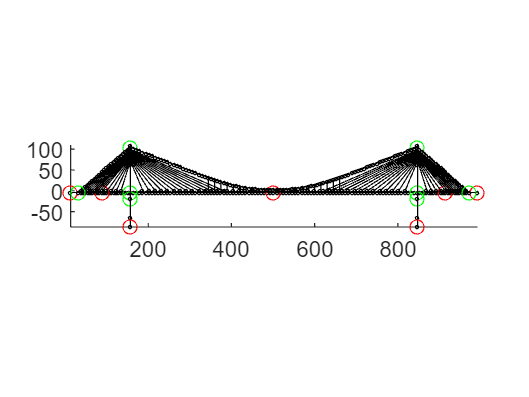

bridges = [];
count_Bridges = length(BridgesCell);
fig = figure;
tiledlayout(fig,count_Bridges,1)
for i=1:count_Bridges
    bridge = BridgesCell{i};
    bridges = [bridges,bridge];
    ax = nexttile;
    bridge.plot("Figure",fig,'Axis',ax);
    view(ax,[0,-1,0]);
end

bridgeobj = OrginalBridges(1);
OutputMethod = bridgeobj.OutputMethod;
% 获取内力
data_InternalForce = OutputMethod.getInternalForce([bridgeobj.getAllLinks.Num],[bridgeobj.getAllBeams.Num])

ans = 8

data_InternalForce = 包含以下字段的 struct :
    num_elements_link: [1153 1154 1155 1156 1157 1158 1159 1160 1161 1162 1163 1164 1165 1166 1167 1168 1169 1170 1171 1172 1173 1174 1175 1176 1177 1178 1179 1180 1181 1182 1183 1184 1185 1186 1187 1188 1189 1190 1191 1192 1193 1194 1195 1196 1197 … ]
       num_INode_link: [984 985 986 987 988 989 990 991 992 993 994 995 996 997 998 999 1000 1001 1002 1003 1004 1005 1006 1007 1008 1009 1010 1011 1012 1013 1014 1015 1016 1017 1018 1019 1020 1021 1022 1023 1024 1025 1026 1027 1028 1029 1030 1031 … ]
       num_JNode_link: [1096 1097 1098 1099 1100 1101 1102 1103 1104 1105 1106 1107 1108 1109 1110 1111 1112 1113 1114 1115 1116 1117 1118 1119 1120 1121 1122 1123 1137 1136 1135 1134 1133 1132 1131 1130 1129 1128 1127 1126 1125 1124 1151 1150 1149 … ]
              Fx_link: [3324727 3.6259e+06 3911717 4159777 4.3654e+06 4529985 4656626 4748697 4809718 4843631 4855149 4850543 4.8351e+06 4810839 3324727 3.6259e+06 3911717 4.1598e+06 4.3654e+06 4529985 4.

% 获取位移
data_Displacement = OutputMethod.getDisplacement([bridgeobj.getAllNodes.Num])

ans = 8

data_Displacement = 包含以下字段的 struct :
    num_nodes: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 … ]
           Ux: [0.0654 0.0636 0.0650 0.0647 0.0643 0.0640 0.0619 0.0633 0.0629 0.0626 0.0622 0.0601 0.0615 0.0612 0.0608 0.0605 0.0584 0.0598 0.0594 0.0591 0.0587 0.0566 0.0580 0.0577 0.0573 0.0570 0.0549 0.0563 0.0559 0.0556 0.0552 0.0532 0.0545 … ]
           Uy: [7.5998e-09 8.7427e-09 7.8263e-09 8.0539e-09 8.2827e-09 8.5123e-09 9.9011e-09 8.9737e-09 9.2052e-09 9.4370e-09 9.6690e-09 1.1057e-08 1.0133e-08 1.0365e-08 1.0596e-08 1.0827e-08 1.2192e-08 1.1286e-08 1.1515e-08 1.1742e-08 1.1968e-08 … ]
           Uz: [-0.0595 -0.0687 -0.0613 -0.0631 -0.0649 -0.0668 -0.0785 -0.0706 -0.0725 -0.0745 -0.0765 -0.0889 -0.0806 -0.0826 -0.0847 -0.0868 -0.0997 -0.0910 -0.0932 -0.0953 -0.0975 -0.1107 -0.1018 -0.1040

% 获取影响线

function [OriginalBridges,NoCableBridges,RSCBridges,OriginalBridgePaths,NoCableBridgePaths,RSCBridgePaths] = ParametricAnalysisLoop(Name_Parameter,Values_Parameter,options)
    arguments
        Name_Parameter
        Values_Parameter
        options.SelfAnchor = true
        options.Pattern_InitPz = 'MeanValue'
        options.ifAnalyze = true
    end
    OriginalBridgePaths = cell(1,length(Values_Parameter));
    NoCableBridgePaths = cell(1,length(Values_Parameter));
    RSCBridgePaths = cell(1,length(Values_Parameter));
    OriginalBridges = [];
    NoCableBridges = [];
    RSCBridges = [];
    % 对每个参数都进行分析并提取结果
    for i=1:length(Values_Parameter)
        value = Values_Parameter(i);
        % 获取Original Model
        [original_bridge,nocable_bridge,RSC_bridge] = getOptimizedHybridBridge(Name_Parameter,value,options.SelfAnchor,options.Pattern_InitPz);
        
        % 输出构建有限元模型的 ANSYS APDL的宏文件
        original_bridge.output;
        
        if options.ifAnalyze
            % 运行优化后的Original Model
            original_bridge.run('ComputingMode','Distributed');
            % 为每个Structure对象获取其对应的Element，存储在Structure.Element属性中
            original_bridge.OutputMethod.getAllNodesAndAllElements();
        end
    
        % 将MATLAB中的Bridge对象存储起来
        OriginalBridgePaths{i} = fullfile(original_bridge.OutputMethod.WorkPath,'OriginalBridge.mat');
        NoCableBridgePaths{i} = fullfile(nocable_bridge.OutputMethod.WorkPath,'NoCableBridge.mat');
        if ~isempty(RSC_bridge)
            RSCBridgePaths{i} = fullfile(RSC_bridge.OutputMethod.WorkPath,'RSCBridge.mat');
        else
            RSCBridgePaths{i} = [];
        end
        
        bridge = original_bridge;
        OriginalBridges = [OriginalBridges,original_bridge];
        save(OriginalBridgePaths{i},'bridge');

        bridge = nocable_bridge;
        NoCableBridges = [NoCableBridges,nocable_bridge];
        save(NoCableBridgePaths{i},'bridge');
        
        if ~isempty(RSCBridgePaths{i})
            bridge = RSC_bridge;
            RSCBridges = [RSCBridges,RSC_bridge];
            save(RSCBridgePaths{i},'bridge');
        end

        % 清除
        Point.Collection.deleteAll();
        Line.Collection.deleteAll();
        Constraint.Collection.deleteAll();
        Coupling.Collection.deleteAll();
        Element.Collection.deleteAll();
        ElementType.Collection.deleteAll();
        Load.Collection.deleteAll();
        Material.Collection.deleteAll();
        Node.Collection.deleteAll();
        Section.Collection.deleteAll();
    end    
end

function BridgeCell = loadBridges(BridgePaths)
    BridgeCell = {};
    for i=1:length(BridgePaths)
        path = BridgePaths{i};
        loaded_data = load(path,'bridge');
        bridge = loaded_data.bridge;
        BridgeCell(1,end+1) = {bridge};
    end
end

function Result = getStaticResult(bridgeobj) % 获取静力结果
    OutputMethod = bridgeobj.OutputMethod;
    workspace = OutputMethod.WorkPath;


    Result = struct;

    % 内力相关
    Result.AxialForce_Girder;
    Result.BendingMoment_Girder;
    Result.BendingMoment_Tower;

    % 变形相关
    Result.Deformation_Girder;
    Result.Deflection_MainSpanMiddle;
    Result.Deformation_Tower;
    Result.XDeformation_TowerTop;
    
    % 缆索索力相关
    Result.F_x;
    Result.Pz_final;

end

function [original_bridge,nocable_bridge,RSC_bridge] = getOptimizedHybridBridge(Name_Parameter,Value_Parameter,SelfAnchored,Pattern_InitPz)
    arguments
        Name_Parameter {mustBeMember(Name_Parameter,{'Ratio_SideMainSpan','Sag','Count_CrossCable'})}
        Value_Parameter
        SelfAnchored {mustBeNumericOrLogical} = true
        Pattern_InitPz {mustBeMember(Pattern_InitPz,{'RSC','MeanValue'})} = 'RSC'
    end

    % 建立完整的协作体系模型
    original_bridge = CableStayedSuspension_Bridge;
    original_bridge.SelfAnchored = SelfAnchored;
    if SelfAnchored
        BridgeType = 'SelfAnchored_Hybrid';
    else
        BridgeType = 'EarthAnchored_Hybrid';
    end
    original_bridge.build_Parametrically(Name_Parameter,Value_Parameter);

    [OriginalModelPath,NoCableModelPath,RSCModelPath] = newComputingFolders(BridgeType,Pattern_InitPz,Name_Parameter,Value_Parameter);

    output_method = OutputToAnsys(original_bridge,...
                    'JobName','OriginalModel',...
                    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
                    'WorkPath',OriginalModelPath,...
                    'MacFilePath',fullfile(OriginalModelPath,'main.mac'),...
                    'ResultFilePath',fullfile(OriginalModelPath,'result.out'));
    original_bridge.OutputMethod = output_method;
    original_bridge.Information.Status = 'Original';
    original_bridge.Information.Type = 'Hybrid';
    original_bridge.Information.SelfAnchored = SelfAnchored;
    original_bridge.Information.Pattern_InitPz = Pattern_InitPz;
    original_bridge.Information.Name_Parameter = Name_Parameter;
    original_bridge.Information.Value_Parameter = Value_Parameter;


    % 建立无索模型（用于优化弯曲应变能，不可以直接使用ANSYS运行）
    nocable_bridge = NoCable_Bridge(original_bridge);
    nocable_bridge.build
    output_method = OutputToAnsys(nocable_bridge,...
                    'JobName','NoCableModel',...
                    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
                    'WorkPath',NoCableModelPath,...
                    'MacFilePath',fullfile(NoCableModelPath,'main.mac'),...
                    'ResultFilePath',fullfile(NoCableModelPath,'result.out'));
    nocable_bridge.OutputMethod = output_method;
    nocable_bridge.getFiniteElementModel;
    nocable_bridge.OutputMethod = output_method;
    nocable_bridge.Information.Status = 'NoCable';
    
    
    % 优化弯曲应变能
    if strcmp(Pattern_InitPz,'RSC')
        % 建立刚性支撑连续梁模型
        RSC_bridge = RigidSupportedContinuousBeam(original_bridge);
        RSC_bridge.build
        output_method = OutputToAnsys(RSC_bridge,...
                        'JobName','NoCableModel',...
                        'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
                        'WorkPath',RSCModelPath,...
                        'MacFilePath',fullfile(RSCModelPath,'main.mac'),...
                        'ResultFilePath',fullfile(RSCModelPath,'result.out'));
        RSC_bridge.OutputMethod = output_method;
        RSC_bridge.Information.Status = 'RSC';
        Pz_0 = RSC_bridge.getSupportedForce()';
        % 优化弯曲应变能
        Map_Init_Pz = containers.Map(0,Pz_0/2);
        nocable_bridge.optimBendingStrainEnergy('MaxIter',30,'DiffMinChange',1e4,'Iter',0,'Map_Iter_Pz',Map_Init_Pz);
    else
        % 以均值为初始设计竖向力，优化弯曲应变能
        RSC_bridge = Bridge.empty();
        nocable_bridge.optimBendingStrainEnergy('MaxIter',30,'DiffMinChange',1e4);
    end

    % 优化后结果
    Map_Pz = nocable_bridge.Result_Iteration.Map_Iter_Pz;
    max_iter = nocable_bridge.Iter_Optimization;
    Pz_final = Map_Pz(max_iter);
    
    % 将优化后结果恢复到Original Model中
    nocable_bridge.solveCableShape(Pz_final);
    X_Pz = nocable_bridge.XCoordOfPz;
    for i=1:length(nocable_bridge.ReplacedStayedCable)
        stayed_cable = nocable_bridge.ReplacedStayedCable(i);
        Point_Bottom = stayed_cable.findGirderPoint();
        X_Bottom = [Point_Bottom.X];
        P_girder_z = zeros(1,length(X_Bottom));
        for j=1:length(X_Pz)
            index = abs(X_Pz(j)-X_Bottom) < 1e-5;
            P_girder_z(index) = Pz_final(j);
        end
        stayed_cable.getP(P_girder_z);
    end
end
function [OriginalModelPath,NoCableModelPath,RSCModelPath] = newComputingFolders(BridgeType,Pattern_InitPz,Name_Parameter,Value_Parameter)
    arguments
        BridgeType {mustBeMember(BridgeType,{'SelfAnchored_Hybrid','EarthAnchored_Hybrid','SelfAnchored_Suspension','CableStayed'})}
        Pattern_InitPz {mustBeMember(Pattern_InitPz,{'RSC','MeanValue'})}
        Name_Parameter {mustBeText}
        Value_Parameter {mustBeNumeric}
    end
    if ~isfolder(fullfile(pwd,'AnsysWorkspace'))
        error('当前文件夹下不存在文件夹./AnsysWorkspace')
    else
        BridgeTypeFolder = fullfile(pwd,'AnsysWorkspace',filesep,BridgeType,filesep);
        InitPzPatternFolder = fullfile(BridgeTypeFolder,Pattern_InitPz,filesep);
        ParameterFolder = fullfile(InitPzPatternFolder,Name_Parameter,filesep);
        ParameterValueFolder = fullfile(ParameterFolder,num2str(Value_Parameter),filesep);
        OriginalModelPath = fullfile(ParameterValueFolder,'OriginalModel',filesep);
        NoCableModelPath = fullfile(ParameterValueFolder,'NoCableModel',filesep);
        RSCModelPath = fullfile(ParameterValueFolder,'RSCModel',filesep);
    end
    if ~exist(OriginalModelPath,'dir')
        mkdir(OriginalModelPath)
    end
    if ~exist(NoCableModelPath,'dir')
        mkdir(NoCableModelPath)
    end
    if ~exist(RSCModelPath,'dir')
        mkdir(RSCModelPath)
    end
end
function [flag,Value] = existVar(Var,options,defaultOptions)
    if isfield(options,Var)
        % 如果存在，则使用传递的值
        flag = true;
        Value = options.(Var);
    else
        % 如果不存在，则使用默认值
        flag = false;
        Value = defaultOptions.(Var);
    end
end